format long

# Task 1 prep

## Data Exploration of BD+55_441

opts = detectImportOptions("BD+55_441.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
preview("BD+55_441.txt",opts)

ans = 8×6 table
      B_time        B_flux       R_time        R_flux       V_time        V_flux 
    ___________    ________    ___________    ________    ___________    ________

     58732.6843    3.497996    58732.68459     1.96183    58732.68445    2.352058
     58732.6843    3.497996    58732.68504    1.942857     58732.6849    2.360458
    58732.68475    3.487289    58732.68549    1.947021    58732.68535    2.329957
     58732.6852    3.450942    58732.68594    1.930594     58732.6858    2.344889
    58732.68565    3.497567    58732.68639    1.942537    58732.68625    2.361048
     58732.6861    3.461555    58732.68684    1.935141    58732.68669    2.333341
    58732.68655    3.431248    58732.68729     1.93129    58732.68714    2.331904
      58732.687    3.455091    58732.6877

BD55_441 = readmatrix("BD+55_441.txt",opts);
whos BD55_441

  Name            Size            Bytes  Class     Attributes

  BD55_441      101x6              4848  double              



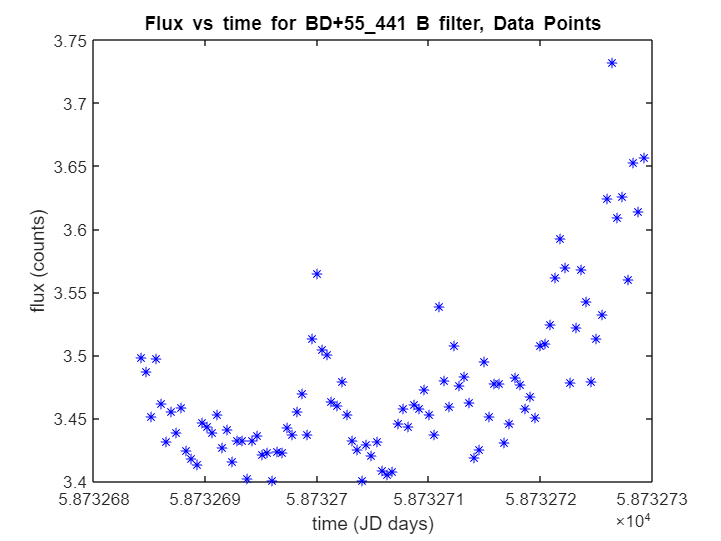


subplot(3,1,1)=plot(BD55_441(:,1),BD55_441(:,2),'*b'); % plotting in blue because B filter is blue light (~400-500 nm)
title('Flux vs time for BD+55\_441 B filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');

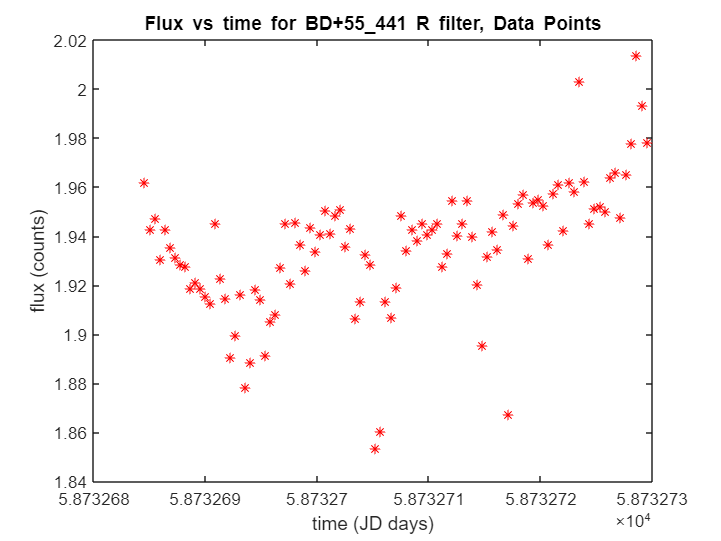

subplot(3,1,2)=plot(BD55_441(:,3),BD55_441(:,4),'*r'); % plotting in red because R filter is red light (~550-800 nm)
title('Flux vs time for BD+55\_441 R filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');

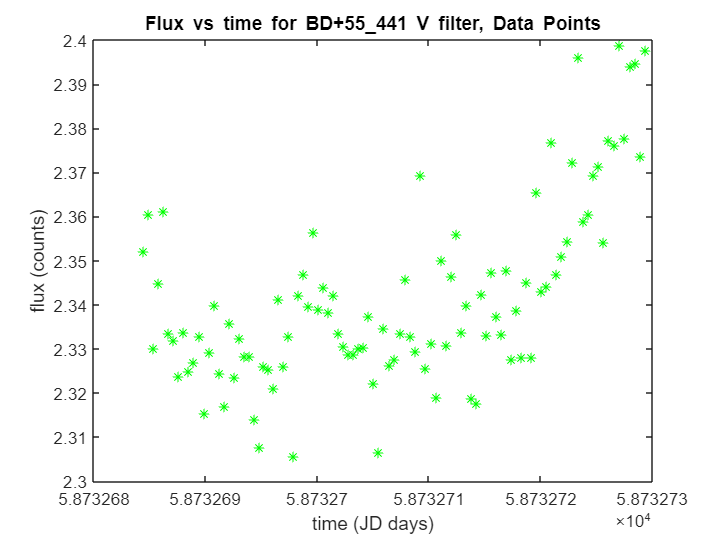


subplot(3,1,3)=plot(BD55_441(:,5),BD55_441(:,6),'*g'); % plotting green but V filter is visible light (~500-700 nm)
title('Flux vs time for BD+55\_441 V filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');

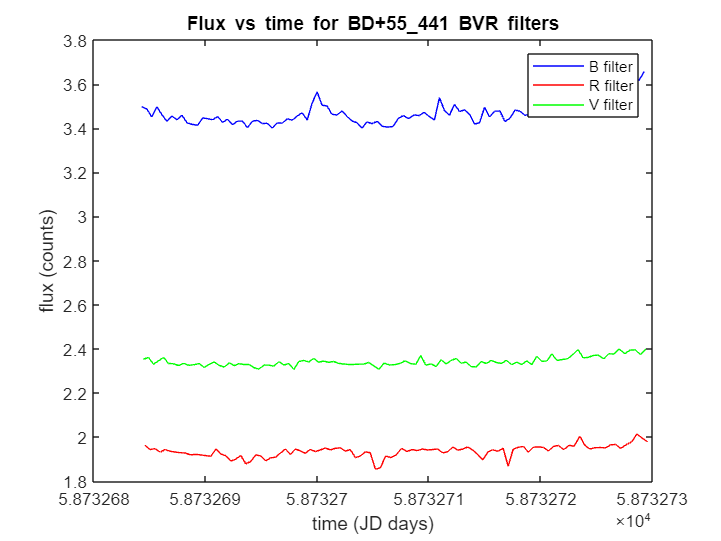


plot(BD55_441(:,1),BD55_441(:,2), 'b')
hold on
plot(BD55_441(:,3),BD55_441(:,4), 'r')
plot(BD55_441(:,5),BD55_441(:,6), 'g')
hold off
title('Flux vs time for BD+55\_441 BVR filters');
xlabel('time (JD days)');
legend('B filter', 'R filter', 'V filter')
ylabel('flux (counts)');


subplot(3,1,1) = plot(BD55_441(:,1),BD55_441(:,2), 'b')

subplot =   3×1×3 graphics array.


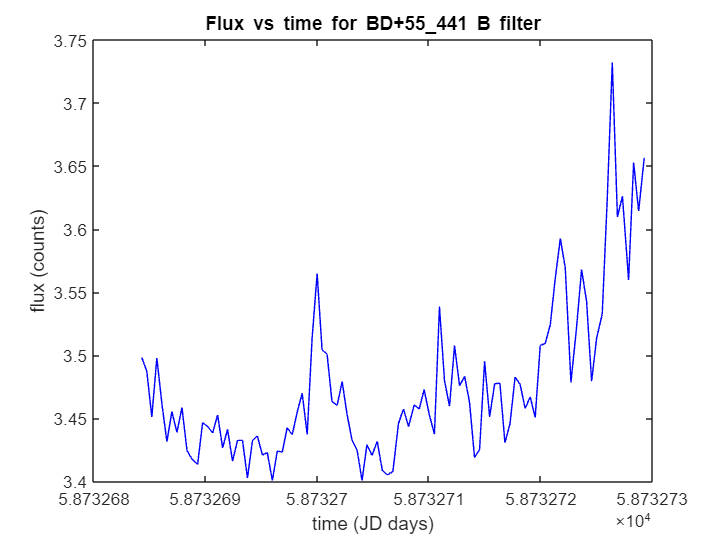

title('Flux vs time for BD+55\_441 B filter');
xlabel('time (JD days)');
ylabel('flux (counts)');


subplot(3,1,2) = plot(BD55_441(:,3),BD55_441(:,4), 'r')

subplot =   3×1×3 graphics array.


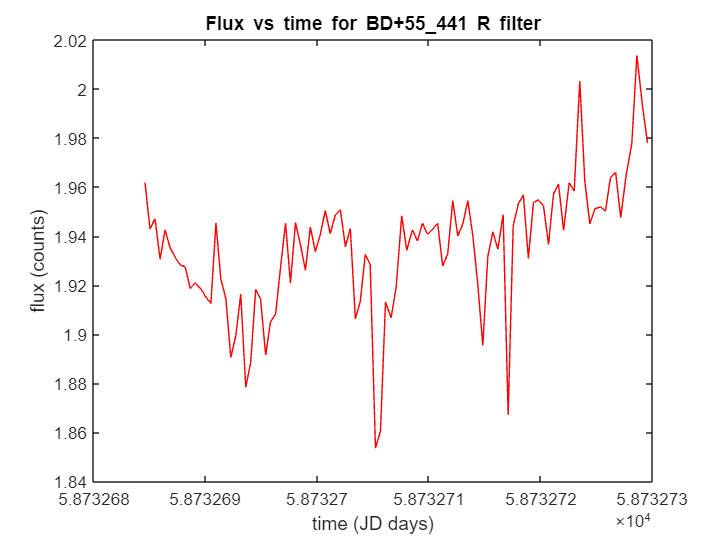

title('Flux vs time for BD+55\_441 R filter');
xlabel('time (JD days)');
ylabel('flux (counts)');


subplot(3,1,3) = plot(BD55_441(:,5),BD55_441(:,6), 'g')

subplot =   3×1×3 graphics array.


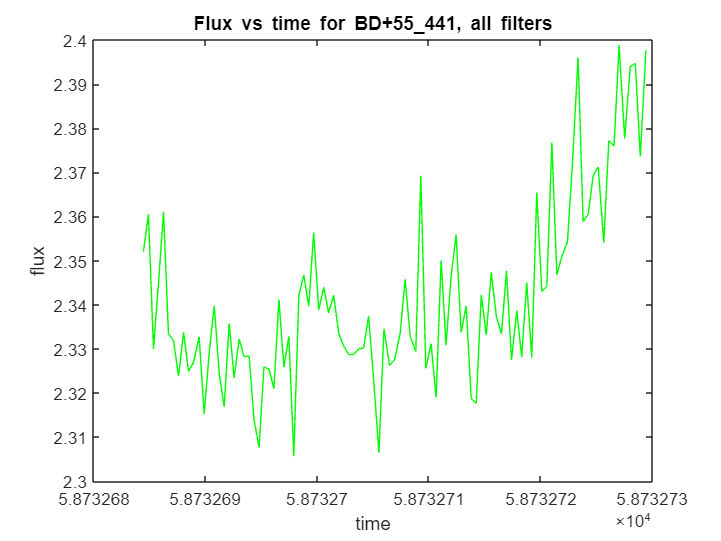

title('Flux vs time for BD+55\_441 V filter');
xlabel('time (JD days)');
ylabel('flux (counts)');

title('Flux vs time for BD+55\_441, all filters');
xlabel('time');
ylabel('flux');

r = abs([0; BD55_441(:,1)] - [BD55_441(:,1);0])

r = 	1.0e+04 *

    5.8733
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


round(mean(r(3:end-1)),8)

ans =      4.543400000000000e-04


round(std(r(3:end-1)),8)

ans =      1.885000000000000e-05


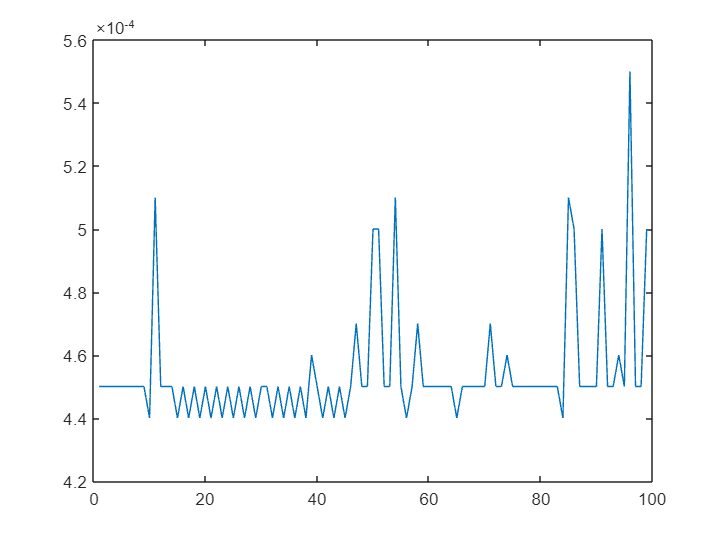

plot(r(3:end-1))

## Input all data

**Text files:**

%BD+48_1098
opts = detectImportOptions("BD+48_1098.txt");

Error using detectImportOptions (line 432)
Unable to find or open 'BD+48_1098.txt'. Check the path and filename or file permissions.

opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
BD48_1098 = readmatrix("BD+55_441.txt",opts); %the matrix data of the text file
%preview("BD+48_1098.txt",opts)
whos BD48_1098
%HD28497
opts = detectImportOptions("HD28497.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD28497 = readmatrix("HD28497.txt",opts); %the matrix data of the text file
%preview("HD28497.txt",opts)
whos HD28497
%HD46131
opts = detectImportOptions("HD46131.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD46131 = readmatrix("HD46131.txt",opts); %the matrix data of the text file
%preview("HD46131.txt",opts)
whos HD46131
%HD88661
opts = detectImportOptions("HD88661.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD88661 = readmatrix("HD88661.txt",opts); %the matrix data of the text file
%preview("HD88661.txt",opts)
whos HD88661
%HD105521
opts = detectImportOptions("HD105521.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD105521 = readmatrix("HD105521.txt",opts); %the matrix data of the text file
%preview("HD105521.txt",opts)
whos HD105521
%HD105521
opts = detectImportOptions("HD105521.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD105521 = readmatrix("HD105521.txt",opts); %the matrix data of the text file
%preview("HD105521.txt",opts)
whos HD105521

**CSV files**

%HD106306
%B_filter
opts = detectImportOptions('HD106306_B.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD106306_B.csv",opts)
HD106306_B = readmatrix("HD106306_B.csv",opts);

%R_filter
opts = detectImportOptions('HD106306_R.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD106306_R.csv",opts)
HD106306_R = readmatrix("HD106306_R.csv",opts);

%V_filter
opts = detectImportOptions('HD106306_V.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD106306_V.csv",opts)
HD106306_V = readmatrix("HD106306_V.csv",opts);

HD106306 = [HD106306_B HD106306_R HD106306_V]; %the matrix data of the text file
whos HD106306
%HD147302
%B_filter
opts = detectImportOptions('HD147302_B.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD147302_B.csv",opts)
HD147302_B = readmatrix("HD147302_B.csv",opts);

%R_filter
opts = detectImportOptions('HD147302_R.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD147302_R.csv",opts)
HD147302_R = readmatrix("HD147302_R.csv",opts);

%V_filter
opts = detectImportOptions('HD147302_V.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD147302_V.csv",opts)
HD147302_V = readmatrix("HD147302_V.csv",opts);

HD147302 = [HD147302_B HD147302_R HD147302_V]; %the matrix data of the text file
whos HD147302

HD152060 and HD209522 can't be described in the same form as the others. Will investigate